clc;
clear;
close all;

## 添加路径

addpath('plane wave\')

## 参数设置

# MLA

lambda = 640e-6;    % 波长
N = 90;           % 微透镜单元采样点数
rla = -0.94;            % 透镜1的曲率半径
d = 0.3;              % 透镜单元边长
t = 1;            % 透镜厚度
n = 1.45706;         % 透镜折射率
beamSize=0.001;       %初始高斯光束腰斑直径
num=floor(beamSize/d*3.5);            %数量
if num<1
    num=1;
end
area1 = num*d;           % 光场的面积
area2=6.9;
distance1 = 1.359;   % 投影距离
distance2 = 298.3;   % 投影距离
distance3=distance2;
distance4=4.164;
rate=d/N;           %采样率（global）
area2=findClosestDivisible(area2,rate);
%diffuserAngle=2.5;   %散射片散射角度
times=500;
peak=0;
SD=0;

# Ex-MLA

rla_ex = -2.23;            % 透镜1的曲率半径
d_ex = 0.2;              % 透镜单元边长

# Fourier Lens

rfl1 = -308.2;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = 308.2;
dfl = 50.8;              % 傅里叶透镜直径
Dfl = area2;              %采样区域
tfl = 5.1;            % 傅里叶透镜厚度
nfl = 1.51528;         % 傅里叶透镜折射率
beam=GaussianBeam(1,beamSize/2,lambda);
beams=GaussianBeam.defocused(beam,10,N*num,rate);
% 在透镜上添加圆形光阑
mask = drawCircle(round(beamSize/(d/N)/2), 0, 0, N*num, N*num);
phase=ones(N*num,N*num);
%beam=beam.*mask;
I=zeros(floor(area2/rate),floor(area2/rate));

# Diffuser

cohLength=1/(0.8333*pi*40);
sigma_f = 3 * cohLength;
sigma_r = sqrt(4 * pi * sigma_f^4 / cohLength^2);

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
[delta_edge_MLA1,delta_mid_MLA1,delta_air_MLA1,t_edge_MLA1]=lensArray_all([rla,inf],d,t,N,num,'');
[delta_edge_MLA2,delta_mid_MLA2,delta_air_MLA2,t_edge_MLA2]=lensArray_all([inf,-rla],d,t,N,num,'');

%% 生成傅里叶透镜厚度函数
[delta_edge_FL,delta_mid_FL,delta_air_FL,t_edge_FL] = lensPhase_all([rfl1,rfl2],dfl,Dfl,tfl,floor(area2/rate),'','');
%% 生成激发微透镜阵列厚度函数
[delta_edge_MLA3,delta_mid_MLA3,delta_air_MLA3,t_edge_MLA3]=lensArray_all([rla_ex,inf],d_ex,t,round(d_ex/rate),round(area2/d_ex),'');

delta_edge_MLA3=single(imresize(delta_edge_MLA3,[size(delta_edge_FL,1),size(delta_edge_FL,2)]));
delta_mid_MLA3=single(imresize(delta_mid_MLA3,[size(delta_mid_FL,1),size(delta_mid_FL,2)]));
delta_air_MLA3=single(imresize(delta_air_MLA3,[size(delta_air_FL,1),size(delta_air_FL,2)]));

delta_edge_MLA1=single(delta_edge_MLA1);
delta_edge_MLA2=single(delta_edge_MLA2);
delta_edge_FL=single(delta_edge_FL);
delta_mid_MLA1=single(delta_mid_MLA1);
delta_mid_MLA2=single(delta_mid_MLA2);
delta_mid_FL=single(delta_mid_FL);
delta_air_MLA1=single(delta_air_MLA1);
delta_air_MLA2=single(delta_air_MLA2);
delta_air_FL=single(delta_air_FL);
t_edge_MLA1=single(t_edge_MLA1);
t_edge_MLA2=single(t_edge_MLA2);
t_edge_FL=single(t_edge_FL);
beams=single(beams);
N=gpuArray(single(N));
num=gpuArray(single(num));
sigma_r=gpuArray(single(sigma_r));
sigma_f=gpuArray(single(sigma_f));
rate=gpuArray(single(rate));

if canUseGPU
    delta_edge_MLA1=gpuArray(delta_edge_MLA1);
    delta_edge_MLA2=gpuArray(delta_edge_MLA2);
    delta_edge_FL=gpuArray((delta_edge_FL));
    delta_mid_MLA1=gpuArray((delta_mid_MLA1));
    delta_mid_MLA2=gpuArray((delta_mid_MLA2));
    delta_mid_FL=gpuArray((delta_mid_FL));
    delta_air_MLA1=gpuArray((delta_air_MLA1));
    delta_air_MLA2=gpuArray((delta_air_MLA2));
    delta_air_FL=gpuArray((delta_air_FL));
    t_edge_MLA1=gpuArray((t_edge_MLA1));
    t_edge_MLA2=gpuArray((t_edge_MLA2));
    t_edge_FL=gpuArray((t_edge_FL));
    beams=gpuArray((beams));
end

## 光场变换

历时 0.742789 秒。
历时 1.641590 秒。
历时 2.358210 秒。
历时 3.052617 秒。
历时 3.842246 秒。
历时 4.582545 秒。
历时 5.322308 秒。
历时 6.081888 秒。
历时 6.836348 秒。
历时 7.613995 秒。
历时 8.397476 秒。
历时 9.185957 秒。
历时 9.959872 秒。
历时 10.799231 秒。
历时 11.602036 秒。


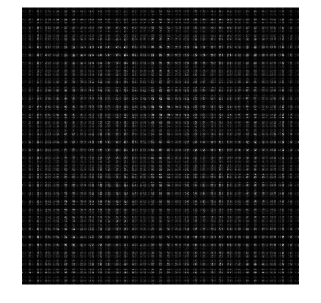

tic
for ii=1:times
    %叠加随机相位
    phase=single(diffuser(sigma_f,sigma_r,rate,[N*num,N*num]));
    beams=beams.*phase;
    beams=transform(beams,area1, lambda, 100, [rate, rate]);
    afterLens=ASMLens(beams,delta_edge_MLA1,delta_mid_MLA1,delta_air_MLA1,t_edge_MLA1,lambda,n,area1);
    F = transform(afterLens, area1, lambda, distance1, [rate, rate]);
    afterLens = ASMLens(F,delta_edge_MLA2,delta_mid_MLA2,delta_air_MLA2,t_edge_MLA2,lambda,n,area1);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    afterLens = ASMLens(F,delta_edge_FL,delta_mid_FL,delta_air_FL,t_edge_FL,lambda,nfl,area2);
    F = transform(afterLens, area2, lambda, distance3, [rate, rate]);
    afterLens = ASMLens(F,delta_edge_MLA3,delta_mid_MLA3,delta_air_MLA3,t_edge_MLA3,lambda,n,area2);
    F = transform(afterLens, area2, lambda, distance4, [rate, rate]);
    %F=afterLens;
    I = I+abs(F).^2;
    %disp(ii)
    %subplot(2,1,1)    
    Inorm=gather((I-min(I,[],'all'))./(max(I,[],'all')-min(I,[],'all')));
    imshow(Inorm,[])
    %plot(Inorm(:,3073))
    hist=imhist(Inorm);
    [~,peak(end+1)]=max(hist);
    SD(end+1)=std(Inorm,0,'all');
    %subplot(2,2,3)
    %plot(peak)
    %subplot(2,2,4)
    %plot(SD)
    drawnow
    toc
end

## 显示结果

I = gather(I);
imshow(I, [])
title('Intensity on homogeneous surface')
